# Spectral Graph Clustering

**Pulizia Ambiente**

clc;
clear;
close all;

## **Generazione Grafo**

- Tramite script

- Dataset GARR

**Grafo Parametrico tramite script**

In questa sezione è possibile utilizzare una funzione esterna *graphN()* per generare un grafo formato da un numero di cluster collegati.

E' necessario indicare i seguenti parametri:

% Numero di cluster
clusters_num = 3;

% Numero di nodi per singolo cluster
nodes = [15, 25, 20];

% Probabilità di connessione dei nodi intra-cluster
p_intra = [0.4, 0.3, 0.5];

% Probabilita di connessione dei nodi inter-cluster (nodi di due cluster diversi)
p_inter = [0 0.05 0.05; 0.05 0 0.05; 0.05 0.05 0];

% Pesi degli archi intra-cluster
weights_intra = {[10, 25, 50, 100]};

% Pesi degli archi inter-cluster
weights_inter = {[1, 5, 10, 25, 50]}

% Esecuzione funzione graphN() che restituisce la matrice di adiacenza del
% grafo e costruzione del grafo G.
A = graphN(clusters_num, nodes, p_intra, p_inter, weights_intra, weights_inter);
G = graph(A);

% Normalizzazione dei pesi degli archi
edge_weights = G.Edges.Weight;
normalized_weights = edge_weights / max(edge_weights);

% Calcolo parametri necessari per la visualizzazione
line_widths = 0.5 + normalized_weights * 2;
edge_labels = edge_weights;

**Dataset GARR**

Questo dataset rappresente la rete del Consorzio GARR reperibile [QUI](https://gins.garr.it/xWeathermap/mapgenT.php?slice=garrt_ip).

Ne sono presenti due versioni:

- Rete GARR (links_partial.txt e nodes_partial.txt)

- Rete GARR + Endpoint esterni (links_complete.txt e nodes_complete.txt)

% Rete GARR
links = readtable('links_partial.txt', 'Delimiter', ' ', 'ReadVariableNames', false);
nodes = readtable('nodes_partial.txt', 'Delimiter', ' ', 'ReadVariableNames', false);

% Rete GARR + Endpoint esterni (es. Google, Microsoft, GEANT, ...)
% links = readtable('links_complete.txt', 'Delimiter', ' ', 'ReadVariableNames', false);
% nodes = readtable('nodes_complete.txt', 'Delimiter', ' ', 'ReadVariableNames', false);

% Operazioni di formattazione dei dati
links.Properties.VariableNames = {'NodoA', 'NodoB', 'Peso'};
nodes.Properties.VariableNames = {'Nodo', 'Coords'};

% Rimuovi i caratteri "[" e "]" dalle coordinate e converti in numeri
nodes.Coords = regexprep(nodes.Coords, '[\[\]]', '');
coords = cell2mat(cellfun(@(x) str2num(x), nodes.Coords, 'UniformOutput', false)); % Converte in matrice numerica

% Rimuovi eventuali duplicati mantenendo solo la prima occorrenza
[unique_nodes, unique_idx] = unique(nodes.Nodo, 'stable');
nodes = nodes(unique_idx, :);
coords = coords(unique_idx, :);



% Creazione del grafo utilizzando i nodi e i pesi caricati
G = graph(links.NodoA, links.NodoB, links.Peso);


% Trova le coordinate per ogni nodo nel grafo
node_coords = zeros(numnodes(G), 2); % Inizializza matrice per le coordinate
for i = 1:numnodes(G)
    node_name = G.Nodes.Name{i};
    idx = find(strcmp(nodes.Nodo, node_name)); % Trova l'indice del nodo
    if ~isempty(idx)
        node_coords(i, :) = coords(idx, :); % Assegna le coordinate
    end
end

G = simplify(G, "sum"); % Rimuovi archi multipli e loop
A = adjacency(G, "weighted"); % Calcola matrice di adiacenza

% Normalizzazione dei pesi degli archi
edge_weights = G.Edges.Weight;
normalized_weights = edge_weights / max(edge_weights);

% Calcolo parametri necessari per la visualizzazione
line_widths = 0.5 + normalized_weights * 2;
edge_labels = edge_weights / 1000;

## Visualizzazione Grafo

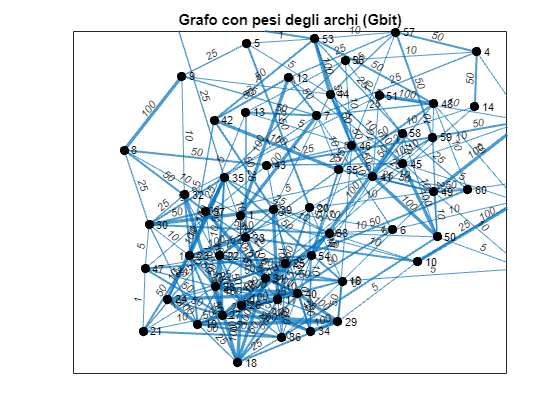

% Visualizzazione del grafo con pesi degli archi visibili
figure;
p = plot(G, 'Layout', 'force', 'EdgeLabel', edge_labels, 'LineWidth', line_widths, 'NodeColor', 'k', 'EdgeAlpha', 0.7, 'MarkerSize', 6); % Aumenta la dimensione dei nodi
title('Grafo con pesi degli archi (Gbit)');

## Eigengap Heuristic

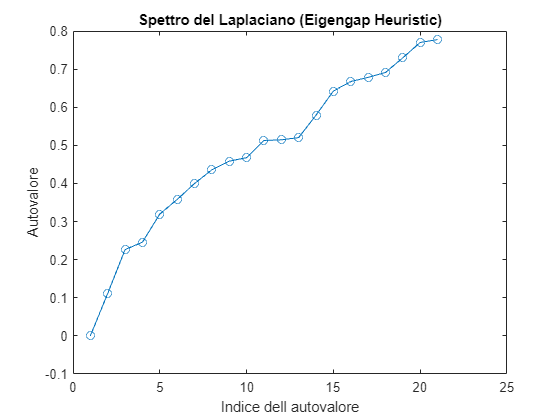

% Stima automatica del numero di cluster
% Necessario tuning del parametro max_k in base alla dimensionalità del
% grafo

max_k = 20;
k = k_eigengap_heuristic(A, max_k);

fprintf('Numero stimato di cluster (eigengap): %d\n', k);

Numero stimato di cluster (eigengap): 2


## Spectral Normalized k-Cut

Cluster 1: 32 nodi
Cluster 2: 28 nodi


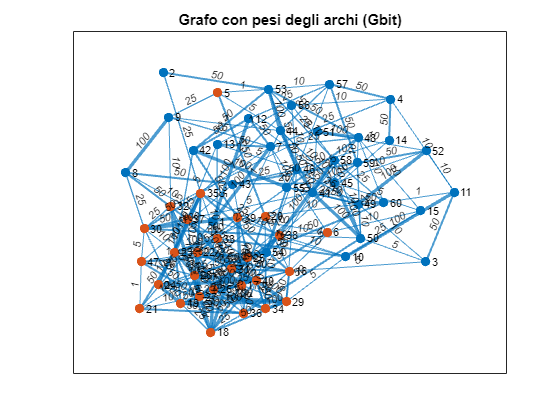

% Applicazione algoritmo spectral normalized k-cut
clusters = spectral_k_norm_cut(A, k);

% Visualizzazione grafo con un colore diverso per ogni cluster
colors = lines(k);
for i = 1:k
    highlight(p, clusters{i}, 'NodeColor', colors(i, :));
    fprintf('Cluster %d: %d nodi\n', i, numel(clusters{i}));
end

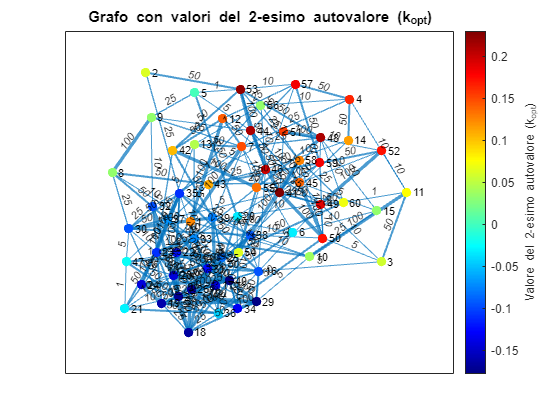

% Visualizzazione del valore del k-esimo autovalore sui nodi del grafo

% Calcolo del vettore proprio associato al k_opt-esimo autovalore
D = diag(sum(A, 2));
D_inv_sqrt = diag(1 ./ sqrt(diag(D) + eps));
L_sym = eye(size(A)) - D_inv_sqrt * A * D_inv_sqrt;

% Calcolo dei primi k autovettori
[V, ~] = eigs(L_sym, k, 'smallestreal'); 
% Vettore proprio associato al k_esimo autovalore
k_opt_eigenvector = V(:, k); 

% Normalizzazione dei valori del vettore proprio per la scala di colori
eigvec_normalized = (k_opt_eigenvector - min(k_opt_eigenvector)) / (max(k_opt_eigenvector) - min(k_opt_eigenvector));

% Creazione di una scala di colori
cmap = jet(256); 
node_colors = cmap(floor(eigvec_normalized * 255) + 1, :);

% Visualizzazione del grafo con colori basati sul k_esimo autovalore
figure;
p = plot(G, 'Layout', 'force', 'EdgeLabel', G.Edges.Weight, 'LineWidth', line_widths, 'NodeColor', 'k', 'EdgeAlpha', 0.7, 'MarkerSize', 6); 
title(sprintf('Grafo con valori del %d-esimo autovalore (k_{opt})', k));

% Aggiorna i colori dei nodi
for i = 1:numnodes(G)
    highlight(p, i, 'NodeColor', node_colors(i, :));
end

% Aggiunta di una barra di colore per la scala
colormap(cmap);
colorbar;
caxis([min(k_opt_eigenvector), max(k_opt_eigenvector)]);
ylabel(colorbar, sprintf('Valore del %d-esimo autovalore (k_{opt})', k));

## **Funzioni Utilizzate**

function k_opt = k_eigengap_heuristic(A, max_k)
    % Calcolo matrice D e L_sym
    D = diag(sum(A, 2));
    D_inv_sqrt = diag(1 ./ sqrt(diag(D) + eps));
    L_sym = eye(size(A)) - D_inv_sqrt * A * D_inv_sqrt;

    % Calcolo autovalori di L_sym
    [~, Lambda_vals] = eigs(L_sym, max_k + 1, 'smallestreal');

    % Ordinamento autovalori di L_sym
    eigvals = sort(diag(Lambda_vals));

    % Calcolo dei gap
    gaps = diff(eigvals);

    % Individuazione gap massimo
    [~, k_opt] = max(gaps);

    % Stampa spettro del Laplaciano
    figure;
    plot(1:max_k+1, eigvals, '-o');
    xlabel('Indice dell autovalore');
    ylabel('Autovalore');
    title('Spettro del Laplaciano (Eigengap Heuristic)');
end

function clusters = spectral_k_norm_cut(A, k)
    % Calcolo matrice D e L_sym
    D = diag(sum(A, 2));
    D_inv_sqrt = diag(1 ./ sqrt(diag(D) + eps));
    L_sym = eye(size(A)) - D_inv_sqrt * A * D_inv_sqrt;

    % Calcolo autovettori di L_sym
    [U, ~] = eigs(L_sym, k, 'smallestreal');

    % Normalizzazione autovettori di L_sym
    U_norm = U ./ vecnorm(U, 2, 2);

    % Esecuzione k-means e calcolo cluster
    labels = kmeans(U_norm, k, 'Replicates', 10);
    clusters = cell(1, k);
    for i = 1:k
        clusters{i} = find(labels == i);
    end
end
